计算静态容性超表面的TE模色散关系

作者：FTT

创建日期：2024.12.11

clear
clc
close all

常量

eps0 = 8.854e-12; %真空介电常数
mu0 = 4*pi*1e-7; %真空磁导率
eta0 = sqrt(mu0/eps0); %真空波阻抗
c = 1/sqrt(mu0*eps0); %真空光速

超表面参数

C = 0.95e-12; %表面电容
f = linspace(0e9, 2e9, 1000); %频率范围
omega = 2*pi*f;

计算传播常数

beta = omega.*sqrt(eps0*mu0*(1 + (omega.^2)*(C^2)*(eta0^2)));
k0 = omega / c; %自由空间波数

绘制色散关系

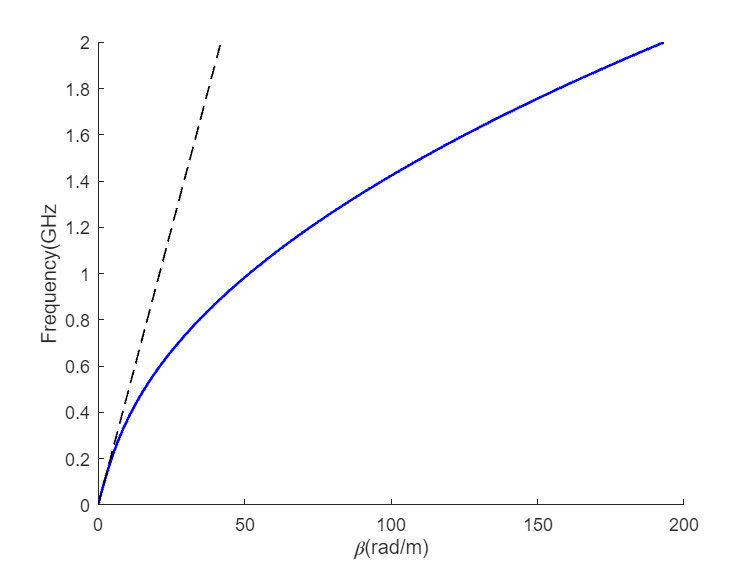

figure;
hold on
plot(beta, f/1e9, 'b-', 'LineWidth', 1.5)
plot(k0, f/1e9, 'k--', 'LineWidth', 1)
xlabel('\beta(rad/m)')
ylabel('Frequency(GHz')